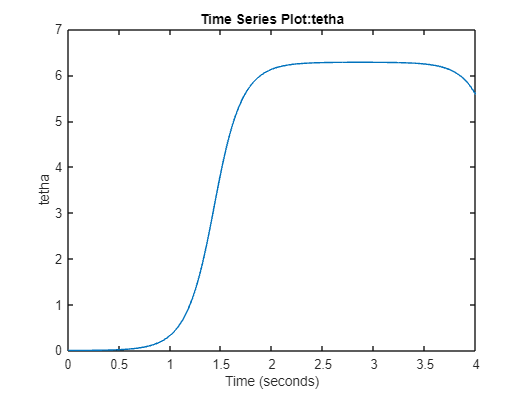

yout = out.simout;
plot (yout);

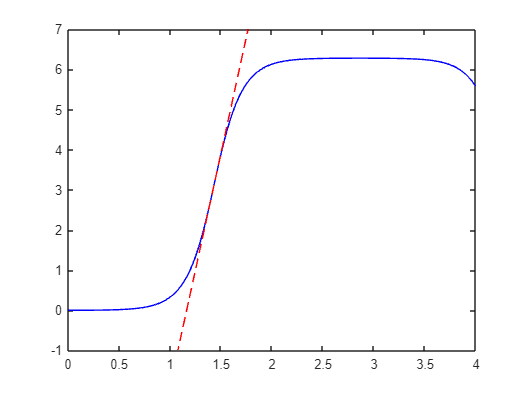

signal = yout.Data(:, 1);
time = yout.Time;
dt = diff(time); 
dsignal = diff(signal) ./ dt; 

[max_slope, idx] = max(dsignal);  

x_tangent = time(idx);             
y_tangent = signal(idx);           


y = max_slope * (time - x_tangent) + y_tangent;

plot(time, signal, 'b');
hold on;
plot(time, y, 'r--');
ylim([-1 7]);

L = (-y_tangent / max_slope) + x_tangent

L = 1.1627

a = max_slope * (- x_tangent) + y_tangent

a = -13.4884

K = 6.28;
B = (0.63*K - y_tangent)/max_slope + x_tangent;
T = B - L;

S1 = (0.5*K - y_tangent)/max_slope + x_tangent;
S2 = (0.67*K - y_tangent)/max_slope + x_tangent;

S_data = [0.5*K 0.67*K];
t_data = [S1 S2];

fun = @(T) [
    K * (1 + ((T(2) * exp(-(t_data(1) - L) / T(2)) - T(1) * exp(-(t_data(1) - L) / T(1))) / (T(1) - T(2)))) - S_data(1);
    K * (1 + ((T(2) * exp(-(t_data(2) - L) / T(2)) - T(1) * exp(-(t_data(2) - L) / T(1))) / (T(1) - T(2)))) - S_data(2)
];

T0 = [0.01, 0.015];

options = optimoptions('fsolve', 'Display', 'iter', 'TolFun', 1e-10, 'TolX', 1e-10, 'MaxIterations', 1000);
solution = fsolve(fun, T0, options);


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3         14.1544                      0.000923               1
     1          4         14.1544              1       0.000923               1
     2          7        0.111985           0.25            4.8            0.25
     3         10      0.00421753       0.104007          0.194           0.625
     4         11      0.00421753       0.173976          0.194           0.625
     5         14      0.00399065      0.0434939          0.423          0.0435
     6         15      0.00399065      0.0434939          0.423          0.0435
     7         18      0.00322645      0.0108735         0.0301          0.0109
     8         19      0.00322645      0.0271837         0.0301          0.0272
     9         22      0.00319021     0.00679592         0.0106          0.0068
    10         23      0.00319021     0.006

disp(['T1 = ', num2str(solution(1))]);

T1 = 0.15933


disp(['T2 = ', num2str(solution(2))]);

T2 = 0.15934


T1=0.15933;
T2=0.15933;